## Communications Project Report

### Annie Lin

#### Silliman'24

#### Goal: To design and verify a communication system that transmits in the presence of cosmic background noise MNIST images from Mars to Earth as intelligible images. The image quality is determined by the purpose of the project, for example, as part of a resume for internship. job interview, or portfolio for application graduate school.

#### Design constraints.

Electrical power (battery voltages = $+A_{max}$ and $-A_{max}$):  


$$A_{max} = 3 \log_{10}(IDN)$$


$A_{max} =  \sqrt{\frac{IDN}{10}}$  $\rightarrow$  ($10 \leq A_{max} < 32$ )

Cosmic radiation noise variance measured at receiver output: 


$$\sigma^2_N = (20\,\log_{10}(IDN))^2$$


Maximum bit error probability for specified image quality.

$PE_{max}=$ 0.1455 

The following code snippet computes these values after you insert your IDN and PE_max values..

clear
clc
IDN = 4585  % replace with your IDN

IDN = 4585

rng(IDN);
var_N = (20*log10(IDN))^2

var_N = 5.3622e+03

sigma_N = sqrt(var_N)

sigma_N = 73.2268

Amax = 3*log10(IDN)

Amax = 10.9840

PE_max = 0.1585 % replace with your value from Lec 3 or new value (first digit your choice,last 3 digits used in IDN)

PE_max = 0.1585

## Desired application

The system design achieves a particular perceptual quality. Describe the application that you have in mind that motivates your choice for the received image quality.

---

For each digit, there is a 28 by 28 pixels greyscale image transmitted. Each pixel consist of 8 bits (1 byte), so a total of 6272 bits are transmitted. We define a high initial PE_max (such as 0.3) and gradually lower it until the MNIST image can be classified (CAP >=0.95). With a given PE, we randomly flip the 6272 bits (we call rand(), and if it is less than PE, the bit is flipped using XOR()). Note that for every bit in a pixel does not have the same level of importance, which means that sometimes bits that are flipped does not yield high errors, whereas some does. For instance, if $bit_8$ was flipped, the byte value would be off by 128, where as if $bit_1$ was flipped, it would only be off by 1. We then recompose the sequence of bits with error back into our image to get the received image with errors. Like I have mentioned before, we adjust the PE value until the image received is intelligible. 

---

## Extract and display MNIST images of IDN 

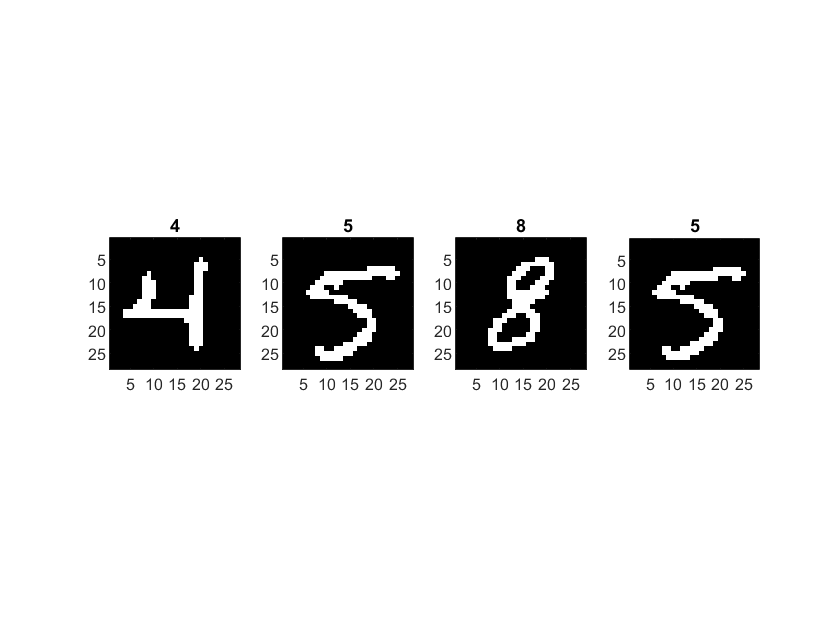

load('mnistb_test.mat')  % load binary MNIST digits
DB = mnistb_test;
[rows cols] = size(DB);
%
mymnist = uint8(zeros(4,785)); % array stores four images
% IDN = 4585
val = [4 5 8 5]; % replace with an array containing your IDN digits
for num = 1:4
    for numseek = 100:rows % examine the MNIST DB to find your digits
        if DB(numseek,1) == val(num)
            mymnist(num,:) = DB(numseek,:);
            break % terminate search loop
        end
    end
    subplot(1,4,num)
    digIm = reshape(mymnist(num,2:785),[28,28]); % form the original 28x28 image
    digIm = digIm'; colormap(gray); imagesc(digIm); axis image; title(mymnist(num,1))
end

- **Explain the intended operation of the condition in the if statement in line 17 by describing the meaning of each variable. **The purpose of line 17 is to essentially iterate through DB, which contains the MNIST data. Each row of DB is a different digit, the first column contains the identifications of the digit (so if the number in column 1 of row x is 8, that entire row (from 2:785) contains the byte value of the pixels that would display the number 8 in an image if you reshaped it and displayed the image). NumSeek corresponds to the row number for the MNIST data, the 1 is for the first number in the row which tells you the digit of the image, val(num) is the digit we are trying to extract, mymnist(num,:) assigns the bit values to a row, which we can use later to transmit images add error etc. What line 17 to line 21 does is that it searches for the digits that you inputed (which is contained in the array *val*) through using an IF statement and iterating through the rows of DB to find the digit. The IF statement would see if a certain row correspondes to the digit we want (by comparing the first value of that row by the value of the digit) and if it is, we extract that and put it in one row of the 4 by 785 matrix. The break function terminates the loop and moves to the next digit. The result does exactly what we want it to: extract the four digits of my IDN, 4585. 

## Form DT of transmitted images.

DB = mymnist;  % from the previous section
[nImages,cols] = size(DB);
nFeatures = cols-1;
DT = zeros(1, 4*nFeatures); % preallocated array for transmitted bits
pDT = 1; % pointer to DT array
for row = 1:nImages
    x = DB(row,2:nFeatures+1);
    for column = 1:nFeatures
        bit = x(column);
        DT(pDT) = bit;
        pDT = pDT+1;
    end
end

- **What does the variable x in line 32 contain? **x extracts the array of bit values for each of the digits from DB (which is a replica of mymnist). Note that it starts from a particular row (first row for first digit, second row for second digit etc.) and column 2, since column 1 contains the digit value. nFeatures is just the number of bits we have per image. 

- **What is the purpose of the **`column`** for loop starting in line 33? **What we are trying to do in this segment of code is that right now we have a 4 by 785 matrix for each of the 4 images with 784 bits + 1 digit (in column 1) for the digit value, but we want 1 array numbers for containing all the bit values of all the digits. line 31 loops through each image, whereas line 33 loops through each bit of each image and assign it to a slot in the DT array (1 by 3136). It does this by having a pointer variable pDT that keeps track of where along the DT array we have already assigned bit values, extract the bit value from the x array, which is basically derived from DB, and assign it to DT(pDT). Next, we add 1 to pDT to assign the next bit value to the next slot in DT in the next loop. 

#### Form DR errors with $PE=PE_{max}$ and display received images.

PE = PE_max

PE = 0.1585

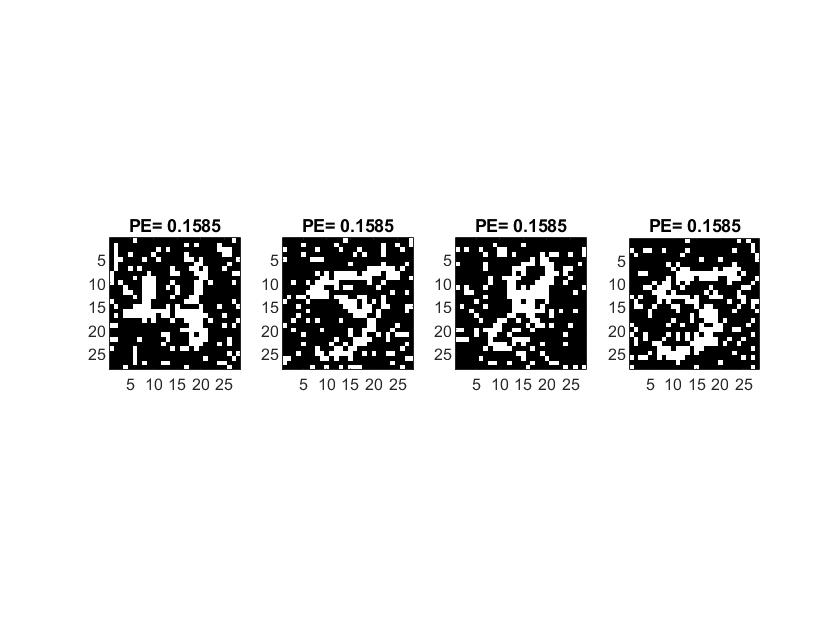

DR = DT; % make copy
for n = 1:length(DR)
    if rand() < PE
        DR(n) = xor(1,DR(n));
    end
end
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im')
    colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

- **Explain how the xor() function in line 43 forms an error. **We want to flip the bit in accordance to our PE value. For each bit value, if rand() give a value less than PE, we want to flip it, and this randomness will allow us to simulate an error of PE in our received data. So how we can flip this bit is through using XOR. 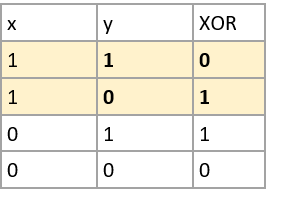What XOR is is that if the two input binary digits are the same, it gives us a 0, if they are different, it give us a 1. By keeping x fixed at 1, (i.e. XOR(1, y)), whatever you input as y will flip the digit of y, so if y was a 1, XOR(1,1)=0, and vice versa. 

- **Explain the steps in lines 48 to 51 convert the DR bit sequence to form the four images. **Line 48 establishes a for loop that iterates through each of the four images. Recall that DR is our received images as an array of bit values with error, so the first 784 bit values is the image of the first digit, the next 784 bit values is the next digit and so on. What line 49 does is that it assigns each 1x784 array of bits for each digit to a variable Im, reshape it so that instead of it being 1x784, it would be a 28x28 matrix, which is the matrix of the image of the digit.Line 50 basically converts Im into a uint8 data so that we can display it as an image and the subplot allows us to display each of the four digits separately next to eachother. The code loops through these four times to get the images of all four digits. 

- **To justify your value of **$PE_{max}$** copy this section code and paste it twice in separate sections that follow immediately to form DR2 and DR3 sequences, where DR2 is formed with **$PE = 2PE_{max}$** and DR3 is formed with **$PE=\frac{PE_{max}}{2}$**. (Change the DR to DR2 or DR3 in all places in the required code) **

- **Comment on the quality of the images formed by DR2 and DR3. **

#### DR2 code

% DR2 code
PE = PE_max*2

PE = 0.3170

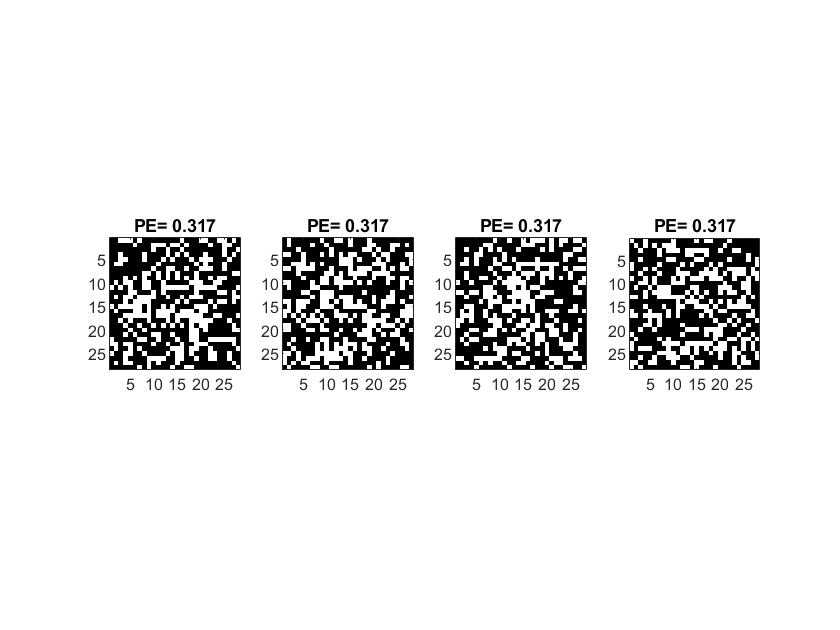

DR2 = DT; % make copy
for n = 1:length(DR2)
    if rand() < PE
        DR2(n) = xor(1,DR2(n));
    end
end
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR2(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im')
    colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

Comparing with DR when PE=0.1585:

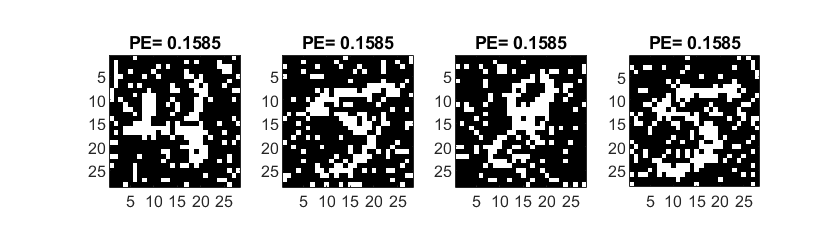

The image generated by DR2 is clearly more distorted. Other than the first image, which is somewhat intelligible, the third, fourth, and fifth digit are not intelligible at all. This makes sense, as we have doubled our PE in DR3, which means that proportionally more bits are going to be flipped. Since we are flipping binary images without error correction, each flipped bit could cause significant error, as it turns a pixel from either black to white or white to black. 

#### DR3 code.

PE = PE_max/2

PE = 0.0793

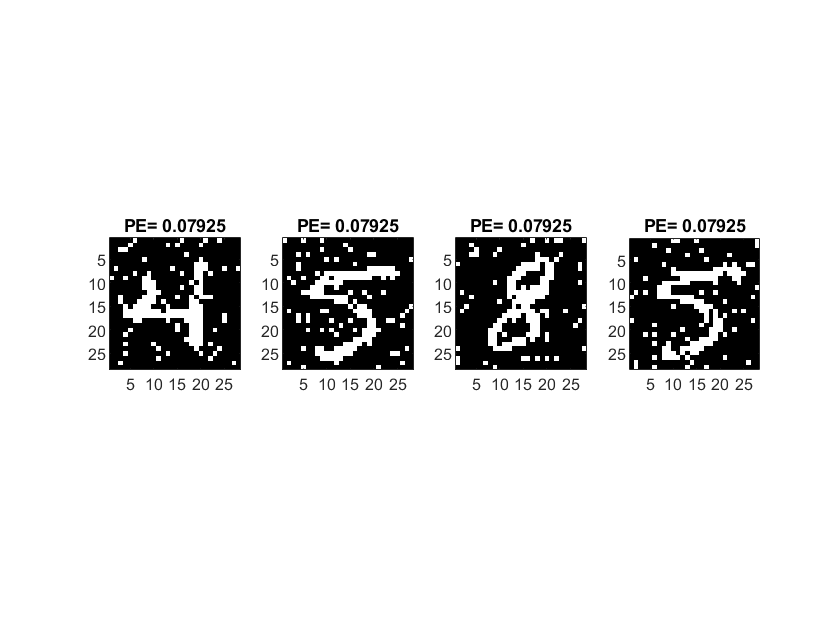

DR3 = DT; % make copy
for n = 1:length(DR3)
    if rand() < PE
        DR3(n) = xor(1,DR3(n));
    end
end
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR3(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im')
    colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

**Comparing with DR when PE=0.1585:**

DR3 clearly has less error compared to DR. For instance, the proportion of flipped bits is less and it looks cleaner. You don't have to squint to see what the digits are. Thus, 0.1585 is a good PE value for image transmission. 

## Simulating a communication system.

#### Design prototype signal.

Compose code snippet setting $N_{sig}= 40$ to form and display a trial prototype signal to transmit bits in the communication channel. 

**Student's Explanation**: in this code, I created a binary signal with an amplitude of Amax and 40 points within the signal. 

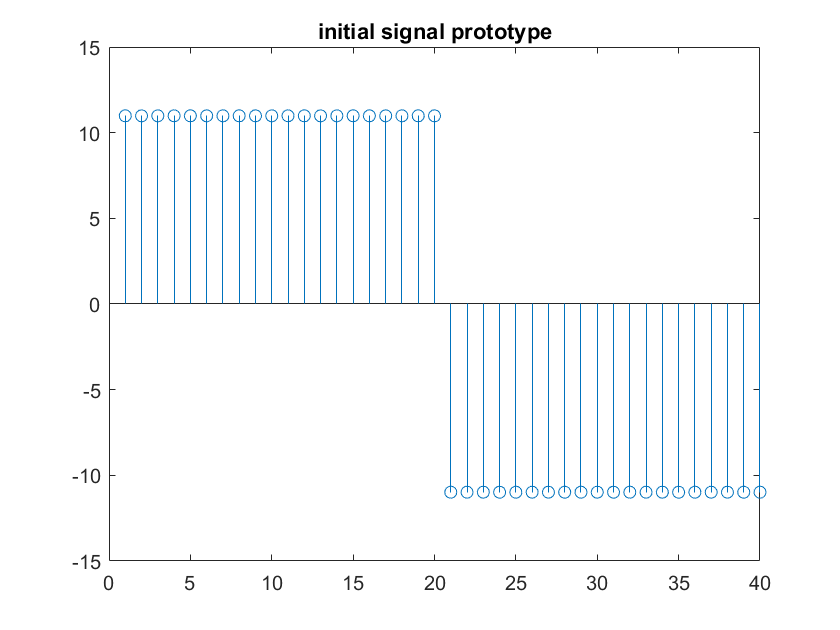

% trial prototype signal s
clf
Nsig=40;
Ndiv2 = Nsig/2;
s = [Amax*ones(1,Ndiv2) -Amax*ones(1,Ndiv2)]; %grabs one half then the negative for the second half and concatenante it 
stem(s)

title('initial signal prototype')

- **Why did you choose this signal type? **I chose this instead of sinusoidal signal because 1. it is easier to manipulate with in terms of calculations and it is easier to create and 2. binary signals give higher energy given the same amplitude (fixed by our initial constraint) and Nsig. This is because in a real life project, we would want to maximize our energy in our signal transmission process given our constraints. 

#### Determine the minimum SNR that produces $PE \leq PE_{max{$. 

The following code estimates the $PE$ value by varying the $E_s/\sigma^2_N$ value and simulating DT bit transmissions by adding noise with variance $\sigma^2_N$.

**Student's explanation of code:** What this code does is that calculates the relationship between SNR and PE by varying sigN. It first set the template = to signal, defined the number of times that we are going to extract new SNR and PE values. It also declares arrays of zero so that we can put our data in them. What the for loop does is that it essentially varies the sigN value (the sigma of the noise), computes the SNR by dividing Es by the variance. Next, we want to collect the PE that comes from that particular SNR. We set our Nerr to 0 for each loop and run through our signal transmission system by adding noise to our signal. If the received bit isn't the same as the transmitted bit, we add one to the number of error Nerr. At the end of the loop, we save the PE value, calculated by dividing the number of error by the number of bits, of that loop to the PE array. We do this 100 times and then we plot the SNR to PE graph so we can extract the SNR value of our PE_max. 

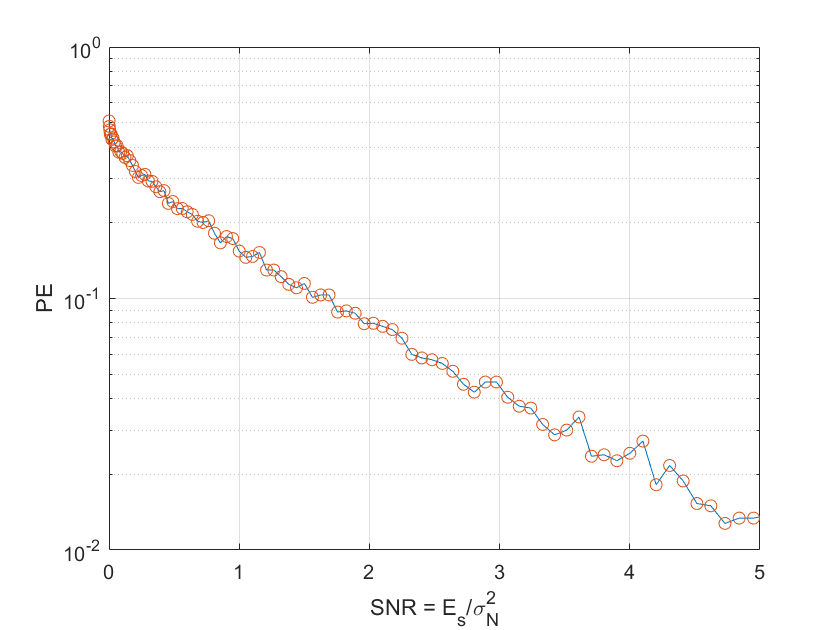

T = s;
Es = round(sum(s.^2));
Nval = 100; PE = zeros(1,Nval); SNR = zeros(1,Nval);
Nbits = length(DT);
for n = 1:Nval
    sigN = sqrt(Es)/(n/40); % a convenient set of values
    SNR(n) = Es/sigN^2;
    Nerr = 0; % initialize count to 0
    for i = 1:Nbits
        sT = s;
        if DT(i) == 0
            sT = -s;
        end
        G = randn(size(sT));
        SR = sT + sigN * G;
        V = sum(T.*SR);
        if V < 0
            DR = 0;
        else
            DR = 1;
        end
        if DR ~= DT(i)
            Nerr = Nerr +1;
        end
    end
    PE(n) = Nerr/Nbits;
end
semilogy(SNR,PE)
hold on
semilogy(SNR,PE,'o');grid on;xlabel('SNR = E_s/\sigma^2_N');ylabel('PE');xlim([0 5]);hold off;

PE_max

PE_max = 0.1585

The plot can be examined more closely by clicking on the + looking glass icon above the plot and placing  cursor over data circle to reveal values. Rerun the section code to reset the plot if needed. Find the SNR value from the linear interpolation between points.

- **What SNR value for PE  is closest to **$PE_{max}$? Around 1.16

- **What value of signal energy **$E_{s,min}$** that achieves your **$PE_{max}$**? **$E_{s,min}$ = 5097 to achieve $PE_{max}$.

I wrote the following code to automatically extract the SNR value when our max probability error exceeds a probability in the PE array. Then I match that index to the SNR array to grab the SNR. 

for i=1:100
    if PE(i)<PE_max
        SNR_max=SNR(i-1);
        break
    end
end
%calculate E_s min
Es_min=round(SNR_max*var_N)

Es_min = 5097

#### Compute $N_{sig}$ for the transmission signal so that it is an even number. 

- **Compute the value of **$N_{sig}$** for your prototype signal from **$E_{s,min}$ $N_{sig}$ is around 42.

- **Verify the prototype gives **$E_s>E_{s,min}$**. Otherwise increase **$N_{sig}$** to a greater even-valued number.**

- **Verify **$E_{s,min}$** and SNR.**

- **Stem plot the protoype signal sT = s.**

- **Stem plot a typical signal in  noise  SR = sT+N.**

% code for calculations and display 
Nsig_min = Es_min/Amax^2;
round(Nsig_min/2)*2

ans = 42

My prototype Es turned out to be greater than the $E_{min}$. This make sense because from the simulation, the SNR value I got is 0.95

Based on our design constraints:


$$Amax=3log_{10}(IDN)$$



$$Var_N=400log_{10}(IDN)^2$$



$$E_s=Amax^2*N_{sig}=9*40*log_{10}(IDN)^2=360*log_{10}(IDN)^2$$



$$E_{smin}=SNR*Var_N=SNR*400*log_{10}(IDN)^2$$


for $E_{smin}<E_s$, $SNR*400*log_{10}(IDN)^2<360*log_{10}(IDN)^2$

$SNR<0.9$, but I got $SNR_{min}$ = 0.95, which is still plausible since the process of determining SNR would have different outcomes if I set different seeds, i.e. it has a degree of randomness to it. Thus, I increased my Nsig to 50 so that my prototype signal would have higher energy than my minimum energy. 

% increasing Nsig to greater even-valued number
Nsig = 50;
Ndiv2 = Nsig/2;
s = [Amax*ones(1,Ndiv2) -Amax*ones(1,Ndiv2)]; %grabs one half then the negative for the second half and concatenante it 
Es = round(sum(s.^2))

Es = 6032

Verifying $E_{smin}$ and SNR:

Es>Es_min %is our prototype energy greater than the minimum energy? If it is 1, then yes it is true

ans = logical
   1

Es_min == Nsig_min*Amax^2 %verifying that Es_min is correct

ans = logical
   1

round(SNR_max)== round(Es_min/var_N) %verifying that the SNR value is truly the SNR of the minimum energy signal. I had to round both because I rounded the originally Es.

ans = logical
   1

SNR of our new signal:

SNR_new=Es/var_N

SNR_new = 1.1249

Plotting the new signal: 

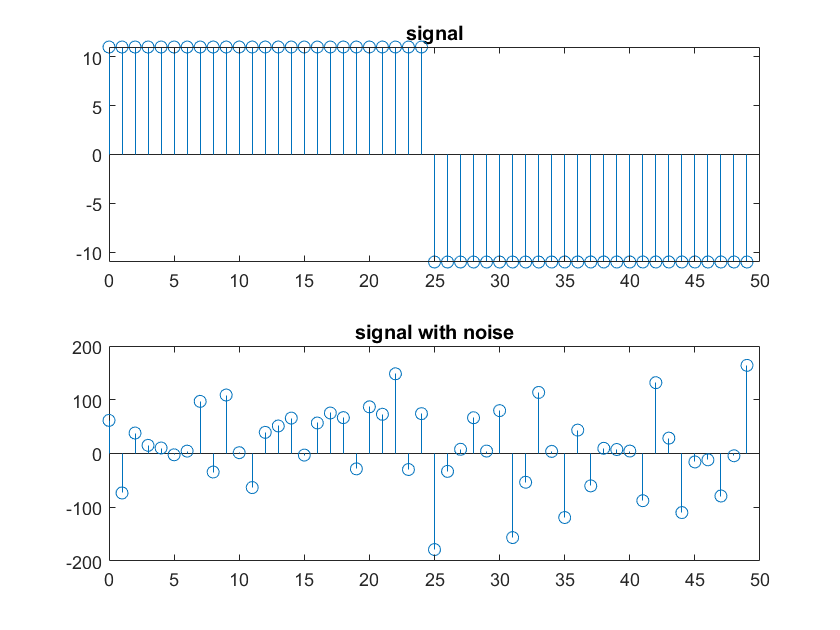

sT=s;
T=s;
t = 0:Nsig-1;
G = randn(size(sT)); % designates Gaussian variable
N = sigma_N*G;  % Gaussian noise
SR=sT+N;
subplot(2,1,1)
stem(t,sT)
title('signal')
subplot(2,1,2)
stem(t,SR)
title('signal with noise')

### Communication system simulation with final prototype signal $s$.  

The following questions can be answered in the code.

- **Modify the communication system simulation above to use the prototype signal and to produce the **$PE_{sim}$** value.**

- **Verify that **$PE_{sim} \leq PE_{max}$**.**

- **Compute the total energy to transmit the four images **$E_{sig,tot}$**.**

% code - It is wise to display the current values of the important
% paramenters to make sure they have not been changed by previous code
sigma_N

sigma_N = 73.2268

SNR_max

SNR_max = 0.9506

Student's explanation: What the following code does is that for each bit within our DT (1x3136), which contains all the bits of all four images, 

received_image=DT;
for i = 1:Nbits
    sT = b2sT(DT(i),s);
    G = randn(size(sT));
    SR = sT + sigma_N * G;
    V = sum(T.*SR);
    DR = detector(V);  % helper functions give concise readable code
    if DR ~= DT(i) % not equal
        Nerr = Nerr +1;
    end
    received_image(i)=DR;
end
PE_sim = Nerr/Nbits

PE_sim = 0.1537

E_tot_sig=Es*Nbits %each signal takes Es=7239, and there are 3136 bits to be transferred 

E_tot_sig = 18916352

Yes $PE_{sim}$ (0.1537) is less than $PE_{max}$ (0.1585). Total Energy needed is around 19 million.

**For fun I just want to show the image that the system transmitted: **

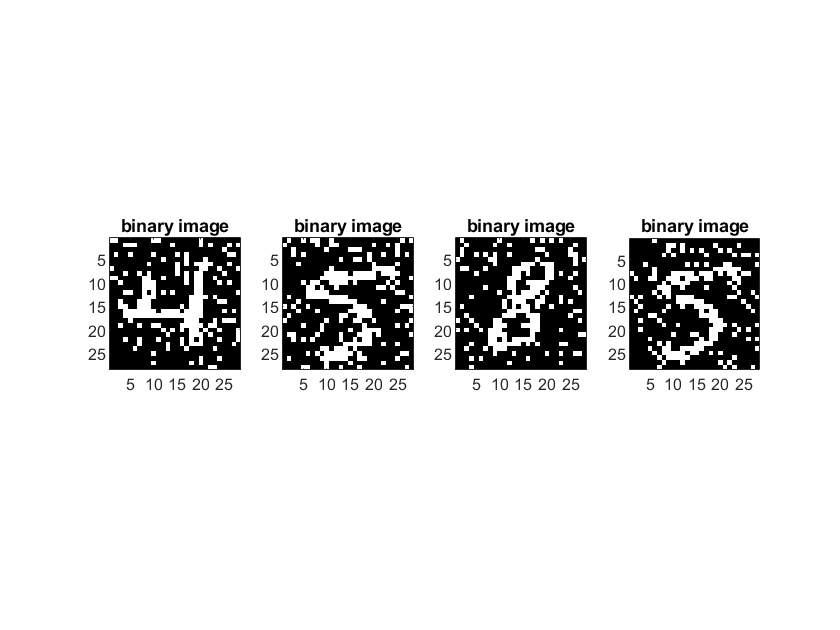

digIm=showImage(received_image);

## Error correction with bit repetition

- **Compose a communication system simulation program that incorporates error correction. **

- **What is the method that modifies the original DT or sT to include repeated bits? **While looping through each bit, we create an array containing that bit plus Nrep-1 redundant bits, which is the basis of our EC process. We then loop through the array containing the redundant bits and do our signal transmission process by adding noise to the transmitted signal and detecting the V value of our received signal. We then assign the received value to our array with the redundant bits so we can calculate the mode afterwards. 

- **What method interpret the received bit value formed by the values of the detected repeated bits? **We use the mode function to determine which bit (1 or 0) from the array of repeated bits is the most recurring. Then we set our bit value for that pixel to that. 

- **Compute error probability using error correction **$PE_{EC}$**. **$PE_{EC}$ = 5.61%

- **The program should form DR_EC, the received bit array.**

- **Display the received images from DR_EC.**

- **Compute the total energy to transmit the four images using error correction **$E_{EC,tot}$**.**

**Set Up**

% EC program
sigma_N

sigma_N = 73.2268

SNR= Es_min/sigma_N^2

SNR = 0.9505

Nrep = 3; %number of times a bit is repeated

## Extract MNIST images of IDN and form $D_T$.

See functions at the bottom for new functions that I wrote to help me clean up the code. 

load('mnist.mat','mnist')
result1=getDigits(IDN, mnist); %I wrote this function. this function grabs the four digits from your IDN and finds the digit array in minist.  

dummyarray =      4     5     8     5


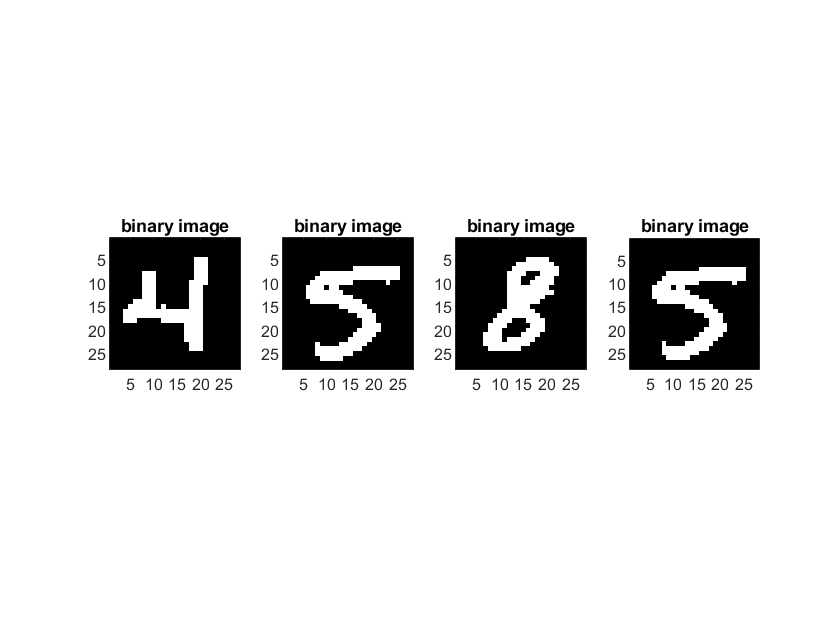

result1=toBinary(result1); %I wrote this function. this function converts image into binary image 
digIm=showImage(result1); %I wrote this function. this function shows the image

## Determining PE of Communication System with EC

**Student's Explanation of Code**: What this code does is that it transmits the image of the four digits with error correction using repeated bit. I first assign the array containing the bit values of all four images to PE_image. Next, I use a for loop to iterate through all bits. For each bit, I create an array of repeated bits (repB) for the EC to add "redundant bits" to transmit. I then loop through each repeated bit in the array and go through our signal transmission process. If a bit is a 1, the signal transmitted is s, and -s for bit value of 0. I then add gaussian noise with standard deviation of sigma_N to the transmitted signal. Next, we match the received signal to our template (which is the same as s) and get a V value. If V>0, the received bit value is 1, and it is 0 for all else. We reassign the received bit value to repB. Once we iterated through each bit in repB, we take the mode of repB to get our received bit value for that particular pixel and assign it to the PE_image. If the received bit value is different than what was transmitted, we add one to our error. 

PE_image=result1;
Nerr=0;
for i = 1:length(result1)
    repB=ones(1,Nrep)*result1(i);
    for x = 1:Nrep
        sT = b2sT(result1(i),s);
        G = randn(size(sT));
        SR = sT + sigma_N * G;
        V = sum(T.*SR);
        DR = detector(V);  % helper functions give concise readable code
        repB(x)=DR;
    end
    bitR=mode(repB);
    if bitR ~= result1(i) % not equal
        Nerr = Nerr +1;
    end
    PE_image(i)=bitR;
end
PE_EC = Nerr/length(result1)

PE_EC = 0.0561

DR_EC=PE_image;

**Display the received images from DR_EC.**

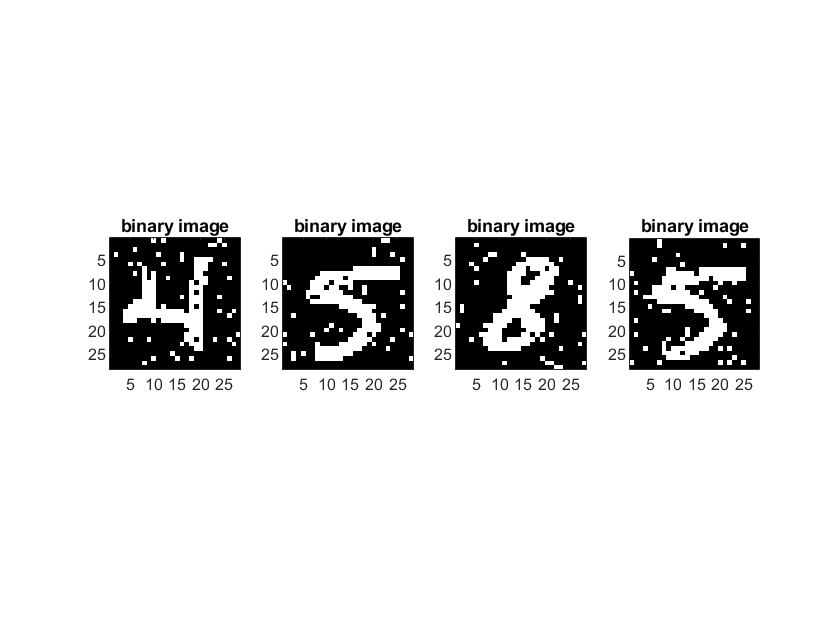

digIm=showImage(DR_EC);

**Total Energy to transmit the four images using error correction **$E_{EC,tot}$**: **

Es*Nrep*length(result1)

ans = 56749056

## **Error Correction: Post transmission - Cleaning up the Image**

**Student's Explanation of Code: **The whole idea behind this post-transmission error correction is the fact that we know that we are transmitting numbers and we know that the strokes of numbers tend to be fluid, as in white pixels tend to clump with white pixels and black pixels tend to clump with black pixels. This code was actually inspired by data block error transmission, it is loosely related. What this code does is that it picks up "lone" pixels that doesn't seem to fit in with its surroundings and flips it. How I do this is that for each pixel, the code looks at the proportion of surrounding pixels. If more than 5 of the pixels touching a black pixel are white pixels, I flip that black pixel, and if less than 3 pixels touching a white pixel are black pixels, I flip that white pixel. 

image_errc=reshape(PE_image,[28,112]);
image_ec=image_errc;
image_ec(1,:)=0; %set border all to black
image_ec(:,1)=0;
image_ec(:,size(image_ec,2))=0;
image_ec(size(image_ec,1),:)=0;
for x=1:3
for i=2:size(image_ec,1)-1
    for j=2:size(image_ec,2)-1
        test=[image_errc(i-1,j-1) image_errc(i-1,j+1) image_errc(i-1,j) image_errc(i,j-1) image_errc(i,j+1) image_errc(i+1,j-1) image_errc(i+1,j) image_errc(i+1,j+1)];
        if sum(test)<3
          image_ec(i,j)=0;  
        end  
    end
end
for i=2:27
    for j=2:111
        test=[image_errc(i-1,j-1) image_errc(i-1,j+1) image_errc(i-1,j) image_errc(i,j-1) image_errc(i,j+1) image_errc(i+1,j-1) image_errc(i+1,j) image_errc(i+1,j+1)];
        if sum(test)>5
          image_ec(i,j)=1;  
        end  
    end
end
image_errc=image_ec;
end
image_ec=reshape(image_ec,[1,3136]);

%Calculate probability of error after image correction
Nerr=0;
for i = 1:length(image_ec)
    if image_ec(i)~=result1(i)
        Nerr=Nerr+1;
    end
end
PE_ic=Nerr/length(image_ec)

PE_ic = 0.0112

The result is dramatic, I was able to reduce the probability of error from 6% to 1%. You can immediately see the improvement in the image after correction. 

**Here, I display the recieved images after all the post-transmission error correction:**

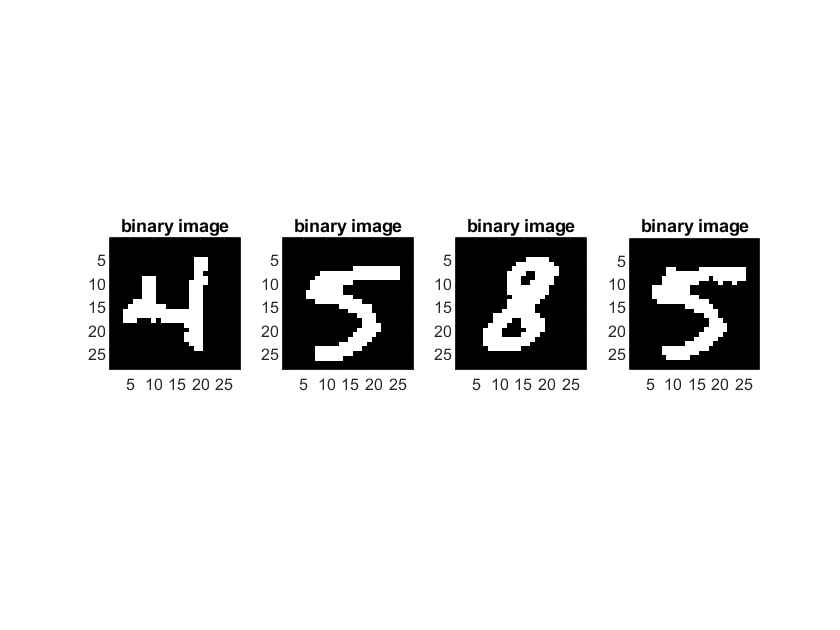

digIm=showImage(image_ec);

It is almost as if there had never been any noise added to the system! This will for sure wow the recruiters at NASA. 

## Testing EC tool by reducing the Energy of the Signal

I wanted to test how powerful this post-transmission error correction tool is. The whole point of this section is to see how low can I set my signal energy so that the error from the communication system with error approximate the probability error from the communication system WITHOUT error correction (PE aproximately 0.154). 

image_test=result1;
Nerr=0;
Nsig_test=8; %reduced from 50 to 8
s_test = [Amax*ones(1,Nsig_test/2) -Amax*ones(1,Nsig_test/2)];
T_test=s_test;
for i = 1:length(result1)
    repB=ones(1,Nrep)*result1(i);
    for x = 1:Nrep
        sT = b2sT(result1(i),s_test);
        G = randn(size(sT));
        SR = sT + sigma_N * G;
        V = sum(T_test.*SR);
        DR = detector(V);  % helper functions give concise readable code
        repB(x)=DR;
    end
    bitR=mode(repB);
    image_test(i)=bitR;
end

image_errc=reshape(image_test,[28,112]);
image_ec=image_errc;
image_ec(1,:)=0;
image_ec(:,1)=0;
image_ec(:,size(image_ec,2))=0;
image_ec(size(image_ec,1),:)=0;
for x=1:3
for i=2:size(image_ec,1)-1
    for j=2:size(image_ec,2)-1
        test=[image_errc(i-1,j-1) image_errc(i-1,j+1) image_errc(i-1,j) image_errc(i,j-1) image_errc(i,j+1) image_errc(i+1,j-1) image_errc(i+1,j) image_errc(i+1,j+1)];
        if sum(test)<3
          image_ec(i,j)=0;  
        end  
    end
end
for i=2:27
    for j=2:111
        test=[image_errc(i-1,j-1) image_errc(i-1,j+1) image_errc(i-1,j) image_errc(i,j-1) image_errc(i,j+1) image_errc(i+1,j-1) image_errc(i+1,j) image_errc(i+1,j+1)];
        if sum(test)>5
          image_ec(i,j)=1;  
        end  
    end
end
image_errc=image_ec;
end
image_ec=reshape(image_ec,[1,3136]);

**Calculating the probability of error after image correction**

Here I loop through each bit in the received data (image_ec) and comparing it to the dataset without error (result1). If a bit from the received data is not the same as the original data, I add one to Nerr. Then I divide Nerr by the total number of bits to get the error. 

Nerr=0;
for i = 1:length(image_ec)
    if image_ec(i)~=result1(i)
        Nerr=Nerr+1;
    end
end
PE_test=Nerr/length(image_ec)

PE_test = 0.0820

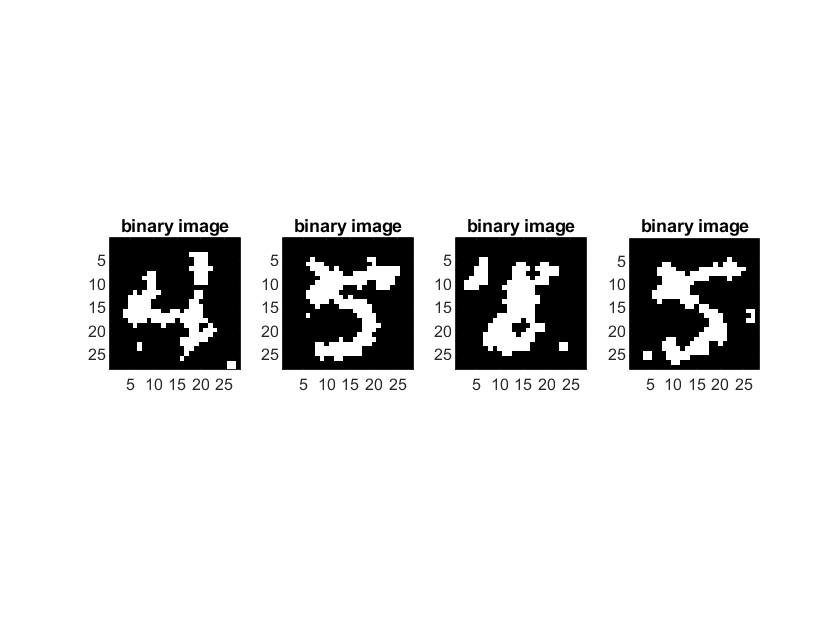

digIm=showImage(image_ec);

I stopped after decreasing Nsig to 8. Eventhough the PE is small, the image is still becoming more and more distorted. This kind of shows the limitation of technology - eventhough the output PE is small, the image is distorted. At Nsig=8, total Es is 

round(8*Amax^2)*Nrep*Nbits

ans = 9078720

Around 9 milion, which is a little more than 2 times less energy than the scenario without Error Correction, but yields similar PE. I calculated total Es by multiplying energy of each signal ($Amax*8$) by the total number of bits transmitted. Since we are repeating bits, we have to count the repeated bits as well, so it would be the number of repeated bits (Nrep) times the number of bits (Nbits).

## Analyze the final communication system design.

- **Compare the values of **$E_{sig,tot}$** and **$E_{EC,tot}$** using reasonable numeric notation. **$E_{sig,tot}$ was 19 million where as $E_{EC,tot}$ was 57 million. 

- **What if any trade-offs were made in your final design. **The tradeoff in our design is that while we are able to get better image quality with error correction, the energy needed to transmit the four images is 3x higher (Since I transmitted 2 redundant bits).

- **For error correction was there a practical maximum value for the number of repetitions? Why? **The probability of flipping one bit given that we have NRep repeated bits and a probability of error of PE is given by  $\sum_{k=NRep/2+1}^{NRep}{Nrep\choose k}PE^k(1-PE)^{NRep-k}$ (classic binomial distribution). To see how the probability plays out:

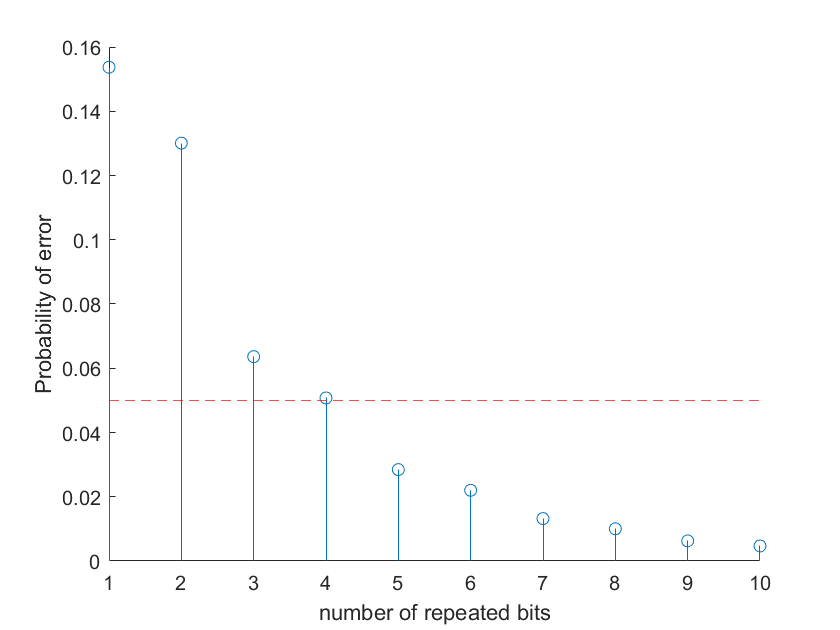

clf
dt_pt=1:10;
PE_flip=zeros(1,10);
for i = 1:10
    binoP=0;
    for x=ceil((i/2)):i
        if mod(i,2)==0
            if x==ceil(i/2)
                binoP=binoP+0.5*nchoosek(i,x)*PE_sim^x*(1-PE_sim)^(i-x);
            end
        else
            binoP=binoP+nchoosek(i,x)*PE_sim^x*(1-PE_sim)^(i-x);        
        end
    end
    PE_flip(i)=binoP;
end
hold on
stem(dt_pt,PE_flip)
yline(0.05, 'r--')
hold off
xlabel('number of repeated bits')
ylabel('Probability of error')

If we want a PE of 5%, anything beyond 4 repeated bits is redundant. I picked 3 because even though there are errors, the image received is clear enough to be intelligble. 

- **Consultant input: If one change in the system specification could be made, what would it be? How would it improve the system performance? What is the associated hardware increase to the system? **We could increase our Amax, and this will increase the system performance by increasing the amplitude of the signal, which increases the signal's energy while keeping Nsig fixed. Increased signal energy allows us to transmit images with less error. We can do this by increasing the voltage in the battery. 

## Summary

- **Summarize the steps used to realize the communication system design.**

- **Did the system accomplish your expectations for the application. If not, what would need to be changed?**

Functions

function sT = b2sT(b,s)
if b == 1
   sT = s;
else
   sT = -s;
end
end

function D = detector(V)
if V<0 
   D = 0;
else
   D = 1;       
end
end

function b = genBits(N)
b = zeros(1,N);
for i = 1:N
    b(i) = 1;  % default value
    if rand() < 0.5
        b(i) = 0; % randomly flip 1 -> 0
    end
end
end

function res = getDigits(IDN, mnist)
res=zeros(1,3136);
dummy=mod(IDN,10);
dummy1=mod((IDN-dummy)/10,10);
dummy2=mod(((IDN-dummy)/10-dummy1)/10, 10);
dummy3=mod((((IDN-dummy)/10-dummy1)/10-dummy2)/10, 10);
dummyarray=[dummy3 dummy2 dummy1 dummy]
for x = 1:4
    for i = 100:300
        if mnist(i,1) == dummyarray(x)
            d1 = mnist(i,:);
            break
        end
    end
    for z = 1:784
    res(z+(x-1)*784)=d1(z+1);
    end
end
end

function digIm=showImage(result1)
for i=1:4
    subplot(1,4,i)
    digIm = reshape(result1((i-1)*784+1:i*784),[28,28]);
    digIm = digIm';
    image(digIm*256)
    colormap(gray)
    axis image
    title('binary image')
end
end

function result1=toBinary(result1)
for i = 1:length(result1)
    if result1(i)>25
        result1(i)=1;
    else
        result1(i)=0;
    end
end
end